# 创建深度学习网络架构

该脚本可创建具有以下属性的深度学习网络:

运行脚本以在工作区变量 `layers` 中创建层。

要了解详细信息，请参阅 [从深度网络设计器生成 MATLAB 代码](matlab:helpview('deeplearning','generate_matlab_code'))。

由 MATLAB 于 2025-06-21 19:47:58 自动生成

## 创建层组

layers = [
    imageInputLayer([28 28 1],"Name","imageinput")
    convolution2dLayer([3 3],6,"Name","conv_1","Padding","same")
    tanhLayer("Name","tanh_1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],16,"Name","conv_2","Padding","same")
    tanhLayer("Name","tanh_2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    fullyConnectedLayer(120,"Name","fc_1")
    fullyConnectedLayer(84,"Name","fc_2")
    fullyConnectedLayer(10,"Name","fc_3")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## 绘制层

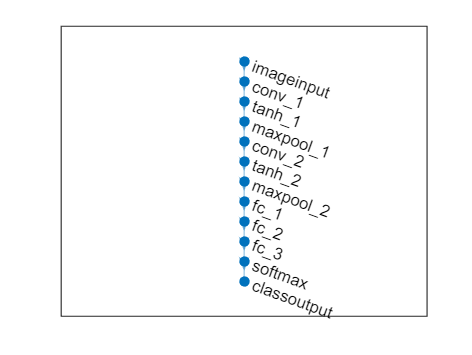

plot(layerGraph(layers));